# 案例：模拟退火算法实现指数拟合

clear;clc;
t = 0.2*(1:3000)';
data = 400*exp(-t/5) + 10*randn(size(t));
tic;
p = SAA_ExpFit(t, data)

p =   403.7607
    4.9852
    0.0000


toc;

历时 0.061923 秒。


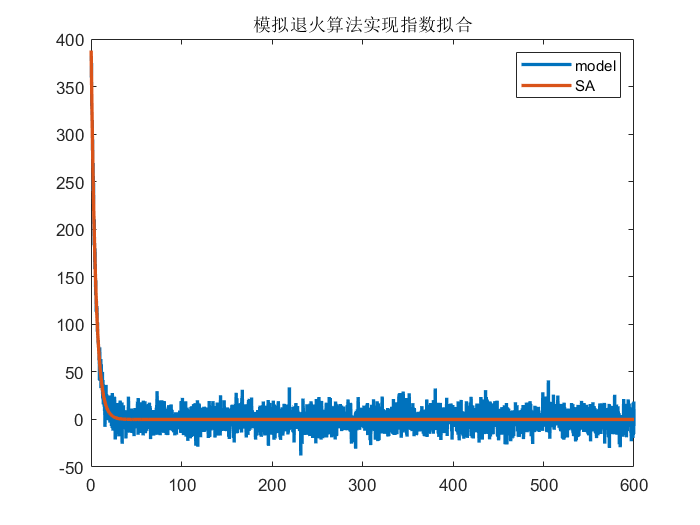

fit = p(1)*exp(-t/p(2)) + p(3);
plot(t, data, t, fit, 'LineWidth', 2)
legend('model', 'SA');
title('模拟退火算法实现指数拟合');

function p0 = SAA_ExpFit(t, Et)
%{
函数功能：模拟退火算法实现指数拟合：y = a*exp(-x/b) + c
输入：
  t：自变量；
  Et：因变量；
输出：
  x_opt：最优解；
  y_opt：适应度（目标函数值）；
%}   
% initial condition
T0= 1000;     % initial temperature
alpha= 0.99;  % annealing factor
N_max= 3000;  % max iterations
% range of varibles
max_sig = max(Et);
Xmin = [0.5*max_sig, -2, 0];           % 下限
Xmax = [1.5*max_sig, 4, 0.5*max_sig];  % 上限；
% initial value
var = rand(1,3).*(Xmax - Xmin) + Xmin;
fun = Obj_Fit(var, t, Et);
% iterative
for i= 1:N_max
  Tk= T0*alpha^(i-1);
    dvar = Tk*sign(rand(1,3)-0.5).*((1+1/Tk).^abs(2*rand(1,3)-1)-1);
    var1 = var + dvar.*(Xmax - Xmin);
    % accept it or not
    if all(var1 >= Xmin) && all(var1 <= Xmax)
      new_fun = Obj_Fit(var1, t, Et);
      if (new_fun <= fun) 
        var = var1;
        fun = new_fun;
      else
        if exp(-(new_fun-fun)/Tk)>rand
          var = var1;
          fun = new_fun;
        end
      end
    end
end
% results
p0 = [var(1), 10^var(2), var(3)]'; 
end


function fitError = Obj_Fit(p0, t ,Et)
A1 = p0(1);
B1 = p0(2);
A0 = p0(3);
f = A1*exp(-t/10^(B1 + eps)) + A0;  
fitError = norm(Et - f);
end